cd GPC

set_parameters_dr7

testing_set_name = 'N-1250-1610-S-35-115-civWVL'

build_catalog_dr7


load('REW_1548_DR12_fine.mat')
load('ShortProcessedDR12.mat')

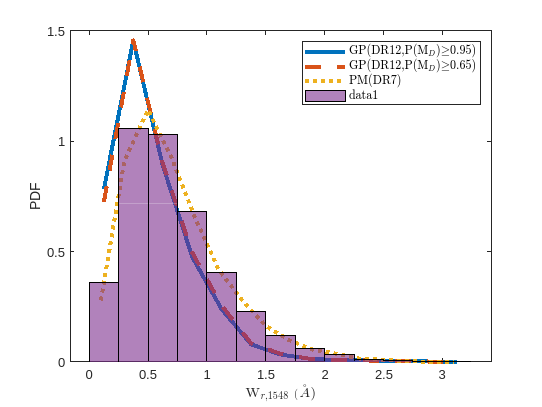

h = histogram(all_EW1(all_EW1>0),'Normalization','pdf');
h.BinWidth = 0.25;

x0 = h.BinEdges;
x0 = x0(2:end) - h.BinWidth/2;
y0 = h.Values;

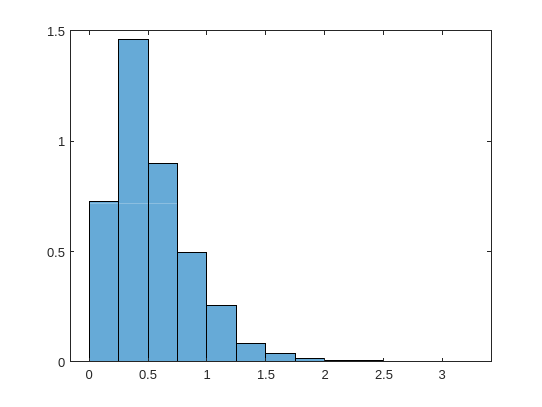

clf
h = histogram(REW_1548_DR12_voigt(all_p_c4>=0.95), 'Normalization','pdf');
h.BinWidth = 0.25;

x1 = h.BinEdges;
x1 = x1(2:end) - h.BinWidth/2;
y1 = h.Values;

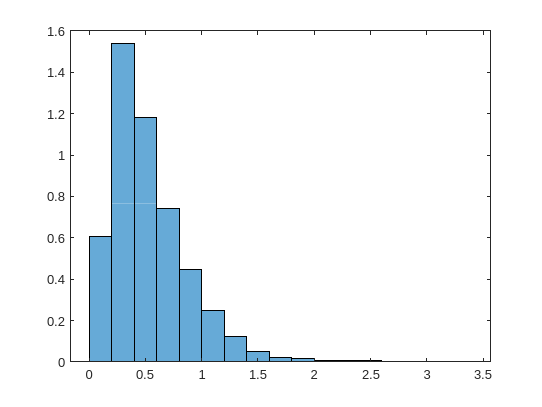

clf
h = histogram(REW_1548_DR12_voigt(all_p_c4>=0.65), 'Normalization','pdf');
h.BinWidth = 0.2;

x2 = h.BinEdges;
x2 = x2(2:end) - h.BinWidth/2;
y2 = h.Values;

fig = figure()

fig =   Figure (41) with properties:

      Number: 41
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties

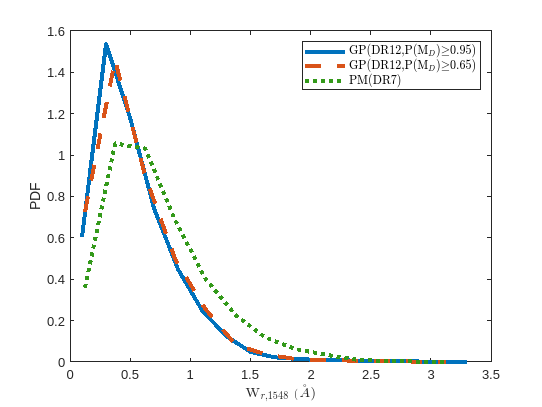

clf
plot(x2,y2, 'LineWidth',3);
hold on 
plot(x1,y1, 'LineWidth',3,'LineStyle','--')
hold on 
plot(x0, y0,'LineStyle',':', 'LineWidth',3, 'Color',[0.2,0.6,0.1])
xlabel('${\rm W}_{r,1548}~(\AA)$', 'Interpreter','latex')
ylabel('PDF')
legend({'GP(DR12,P(M$_D$)$\ge$0.95)',...
         'GP(DR12,P(M$_D$)$\ge$0.65)',...
         'PM(DR7)'}, 'Interpreter','latex')
exportgraphics(fig, 'REW_DR7_DR12.png','Resolution',800)

clf()
fig=figure()

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties

DR = REW_1548_DR12_voigt./REW_1550_DR12_voigt;
ind = (REW_1550_DR12_voigt>0) & (REW_1548_DR12_voigt>0) & (all_p_c4>0.95);
h = histogram(DR(DR<quantile(DR, 0.9995) & DR>quantile(DR,0.0005)), 'NumBins',25)

h =   Histogram with properties:

             Data: [443457×1 double]
           Values: [6477 7209 3859 4116 5822 9519 13174 17741 24140 32726 41352 54067 69680 80598 65467 7355 0 27 51 40 18 10 7 1 1]
          NumBins: 25
         BinEdges: [1.0500 1.1100 1.1700 1.2300 1.2900 1.3500 1.4100 1.4700 1.5300 1.5900 1.6500 1.7100 1.7700 1.8300 1.8900 1.9500 2.0100 2.0700 2.1300 2.1900 2.2500 2.3100 2.3700 2.4300 2.4900 2.5500]
         BinWidth: 0.0600
        BinLimits: [1.0500 2.5500]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties

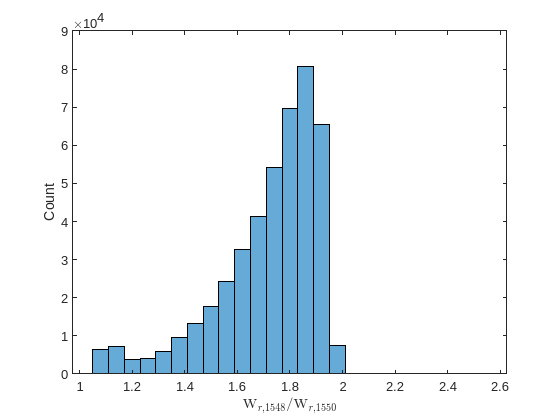

% xlim([1,2.1])
xlabel('${\rm W}_{r,1548}/{\rm W}_{r,1550}$', 'Interpreter','latex')
ylabel('Count')
exportgraphics(fig, 'DRHist.png', 'Resolution', 800)

aa(1,1) = min([])

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is
0-by-0.